## Lab3.9

(a)

题目要求：用lsim仿真系统对x(t)在范围内的响应y(t)，同时画出这两个图像，并注意幅值和相位变化，用频率响应解释变化。

分析：由H(jw) = 1*(1+jw)^-1 ，变换x(t)，

由x(t)经过 H(jw)的变换得出y(t):

clear;
t = linspace(0,20,1000);
x = cos(t);
A = [1 1];
B = 1;
y = lsim(B, A, x, t)'

y =          0    0.0198    0.0392    0.0583    0.0769    0.0951    0.1129    0.1303    0.1473    0.1639    0.1802    0.1960    0.2114    0.2264    0.2410    0.2552    0.2690    0.2825    0.2955    0.3081    0.3203    0.3321    0.3436    0.3546    0.3652    0.3755    0.3853    0.3948    0.4039    0.4125    0.4208    0.4287    0.4362    0.4433    0.4501    0.4564    0.4624    0.4680    0.4732    0.4781    0.4825    0.4866    0.4903    0.4937    0.4967    0.4993    0.5015    0.5034    0.5050    0.5061


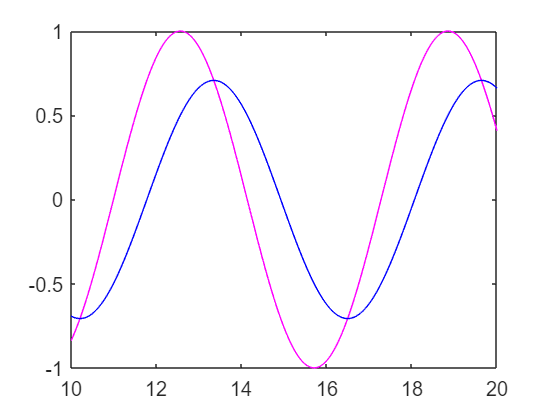

figure
plot(t, x, '-m', t, y, '-b'),axis([10 20 -1 1]);

结论：由图可得，输出的幅值减小，相位移动，原因在于：

        低频的输入信号能量被消耗，导致输出信号的幅值减小；

        RC电路的阻抗使得信号的相角发生改变。

(b)

题目要求：通过限幅器获得一个方波，并仿真系统对方波的响应，绘制输出。

x2 = cos(t);
x2(x2 > 0) = ones(size(x2(x2>0)));
x2(x2 < 0) = -ones(size(x2(x2<0)));
y2 = lsim(B, A, x2, t)'

y2 =          0    0.0198    0.0392    0.0583    0.0770    0.0953    0.1132    0.1308    0.1480    0.1649    0.1814    0.1977    0.2136    0.2291    0.2444    0.2594    0.2741    0.2885    0.3026    0.3164    0.3299    0.3432    0.3562    0.3690    0.3815    0.3938    0.4058    0.4176    0.4291    0.4404    0.4515    0.4624    0.4730    0.4835    0.4937    0.5038    0.5136    0.5232    0.5327    0.5420    0.5510    0.5599    0.5687    0.5772    0.5856    0.5938    0.6018    0.6097    0.6175    0.6251


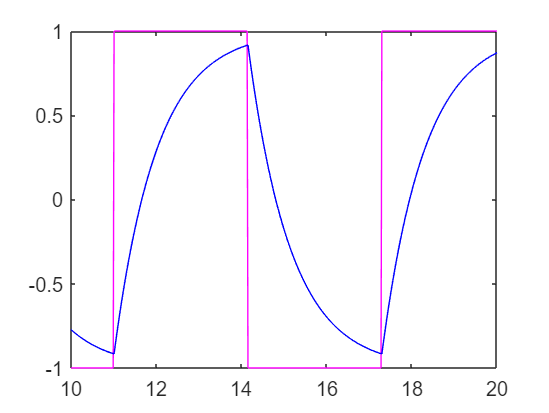

figure
plot(t, x2, '-m', t, y2, '-b'),axis([10 20 -1 1]);

结论：如答图所示。

(c)

题目要求：解析法算出方波信号x2的CTFS，

如图，

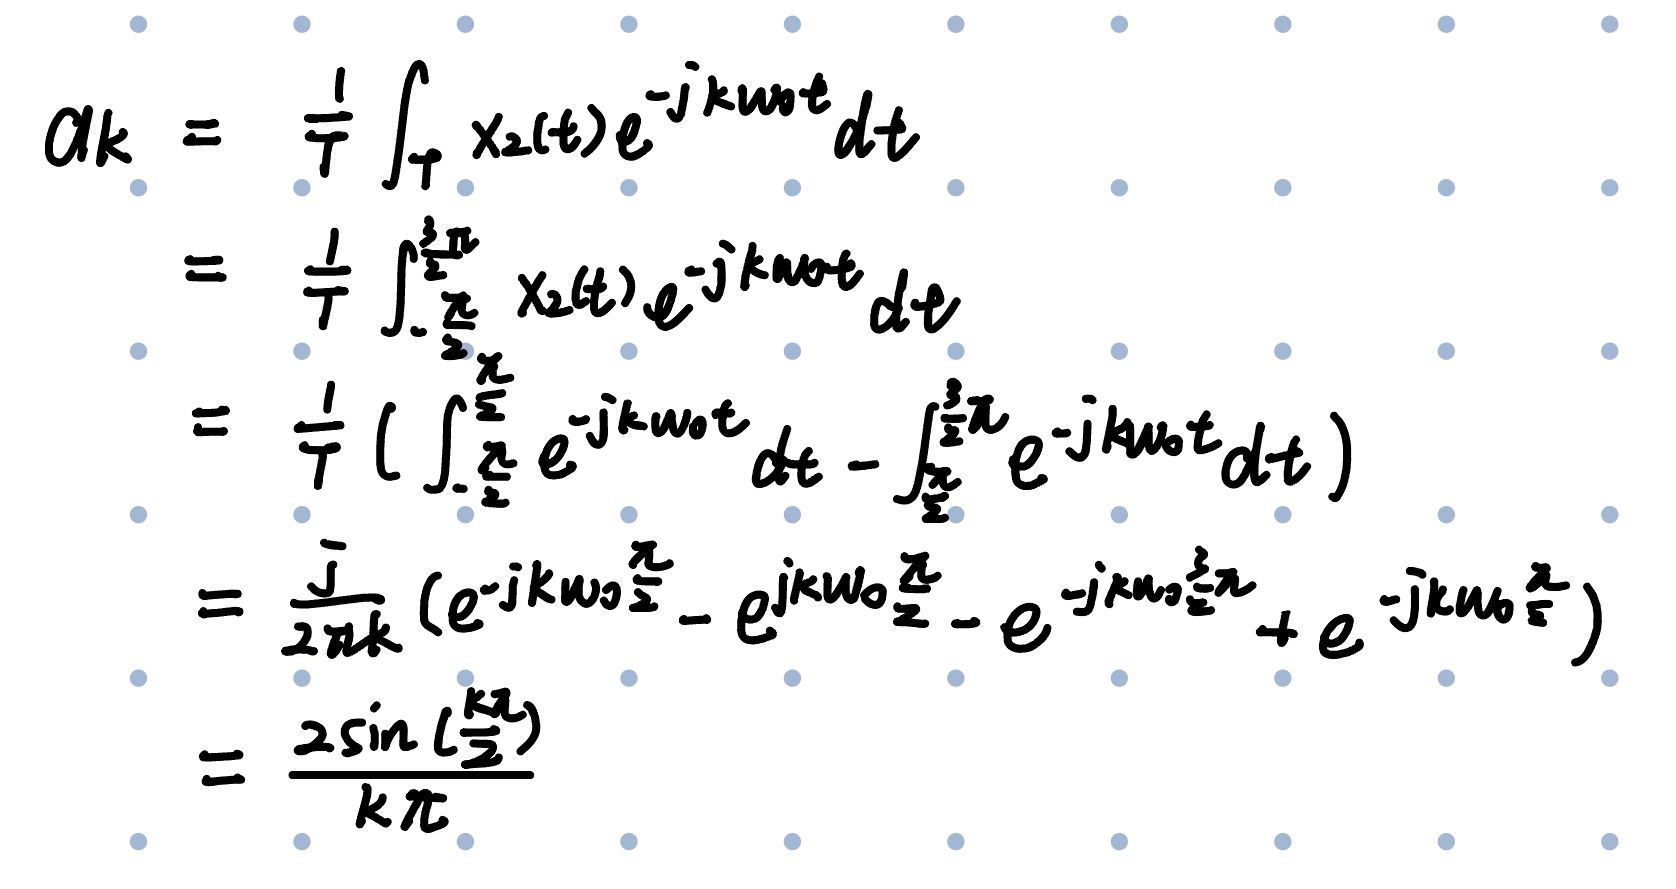

方波信号s与方波信号x2的CTFS系数关系如图所示：

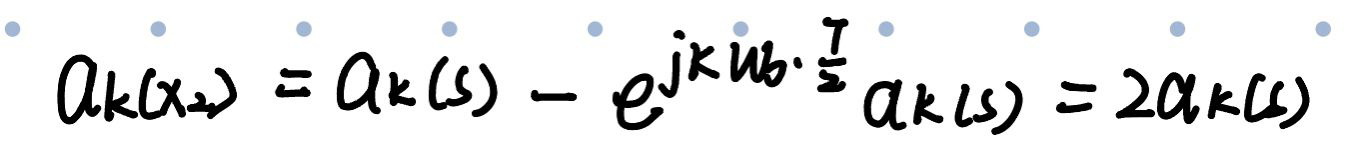

ak = [];
% 取出非零元
for k = 1:10
    ak(k) = 2 * sin(k*pi/2) / k / pi;
end
ak_p = [ak(1) ak(3) ak(5) ak(7) ak(9)]

ak_p =     0.6366   -0.2122    0.1273   -0.0909    0.0707


ak_n = ak_p

ak_n =     0.6366   -0.2122    0.1273   -0.0909    0.0707


s1 = ak_p(1) * exp(1j*t) + ak_n(1) * exp(-1j*t)

s1 =     1.2732    1.2730    1.2722    1.2709    1.2692    1.2669    1.2641    1.2608    1.2569    1.2526    1.2478    1.2425    1.2367    1.2304    1.2236    1.2163    1.2085    1.2002    1.1915    1.1822    1.1725    1.1624    1.1517    1.1406    1.1291    1.1171    1.1046    1.0917    1.0784    1.0646    1.0504    1.0358    1.0208    1.0053    0.9895    0.9733    0.9566    0.9396    0.9222    0.9045    0.8863    0.8679    0.8490    0.8299    0.8104    0.7906    0.7704    0.7500    0.7292    0.7082


s2 = ak_p(2) * exp(3j*t) + ak_n(2) * exp(-3j*t)

s2 =    -0.4244   -0.4236   -0.4214   -0.4175   -0.4122   -0.4054   -0.3972   -0.3875   -0.3764   -0.3639   -0.3501   -0.3351   -0.3189   -0.3015   -0.2830   -0.2635   -0.2431   -0.2218   -0.1996   -0.1768   -0.1533   -0.1293   -0.1048   -0.0799   -0.0547   -0.0294   -0.0039    0.0216    0.0470    0.0722    0.0972    0.1218    0.1460    0.1696    0.1927    0.2150    0.2366    0.2573    0.2771    0.2959    0.3136    0.3302    0.3456    0.3598    0.3727    0.3842    0.3943    0.4030    0.4103    0.4161


s3 = ak_p(3) * exp(5j*t) + ak_n(3) * exp(-5j*t)

s3 =     0.2546    0.2534    0.2496    0.2433    0.2345    0.2234    0.2101    0.1947    0.1773    0.1581    0.1374    0.1153    0.0920    0.0678    0.0429    0.0176   -0.0078   -0.0332   -0.0583   -0.0828   -0.1064   -0.1290   -0.1503   -0.1701   -0.1882   -0.2044   -0.2185   -0.2305   -0.2402   -0.2474   -0.2522   -0.2545   -0.2542   -0.2513   -0.2460   -0.2382   -0.2280   -0.2155   -0.2008   -0.1842   -0.1657   -0.1455   -0.1239   -0.1011   -0.0772   -0.0526   -0.0274   -0.0020    0.0235    0.0487


s4 = ak_p(4) * exp(7j*t) + ak_n(4) * exp(-7j*t)

s4 =    -0.1819   -0.1801   -0.1748   -0.1661   -0.1541   -0.1390   -0.1213   -0.1012   -0.0791   -0.0554   -0.0307   -0.0053    0.0201    0.0452    0.0693    0.0922    0.1132    0.1319    0.1481    0.1614    0.1716    0.1783    0.1816    0.1813    0.1774    0.1701    0.1594    0.1457    0.1290    0.1098    0.0885    0.0654    0.0411    0.0159   -0.0095   -0.0348   -0.0594   -0.0828   -0.1046   -0.1244   -0.1417   -0.1562   -0.1677   -0.1759   -0.1806   -0.1818   -0.1795   -0.1736   -0.1643   -0.1518


s5 = ak_p(5) * exp(9j*t) + ak_n(5) * exp(-9j*t)

s5 =     0.1415    0.1392    0.1324    0.1213    0.1063    0.0878    0.0665    0.0431    0.0182   -0.0072   -0.0324   -0.0565   -0.0789   -0.0986   -0.1152   -0.1281   -0.1368   -0.1410   -0.1407   -0.1359   -0.1266   -0.1133   -0.0963   -0.0761   -0.0535   -0.0292   -0.0039    0.0215    0.0462    0.0694    0.0904    0.1084    0.1230    0.1335    0.1397    0.1414    0.1386    0.1312    0.1196    0.1041    0.0853    0.0636    0.0400    0.0150   -0.0105   -0.0356   -0.0595   -0.0816   -0.1010   -0.1171


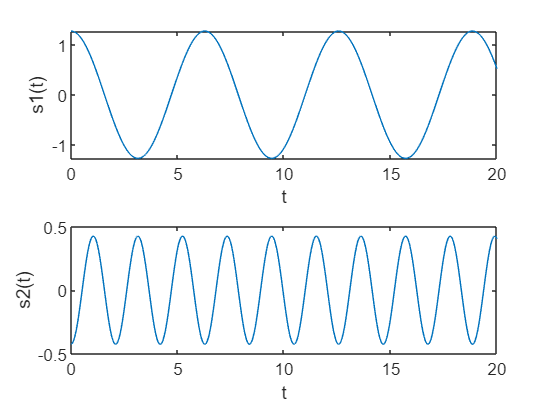

figure
subplot(2,1,1), plot(t, s1), xlabel('t'), ylabel('s1(t)');
subplot(2,1,2), plot(t, s2), xlabel('t'), ylabel('s2(t)');

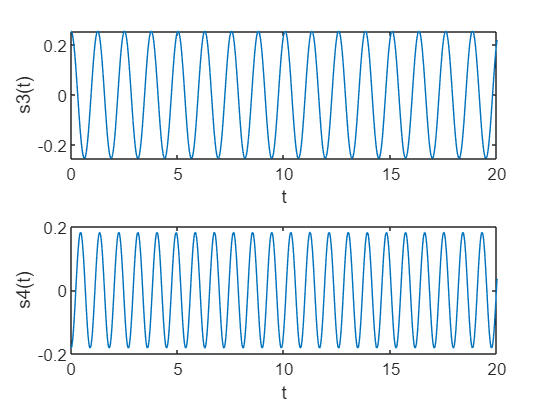

figure
subplot(2,1,1), plot(t, s3), xlabel('t'), ylabel('s3(t)');
subplot(2,1,2), plot(t, s4), xlabel('t'), ylabel('s4(t)');

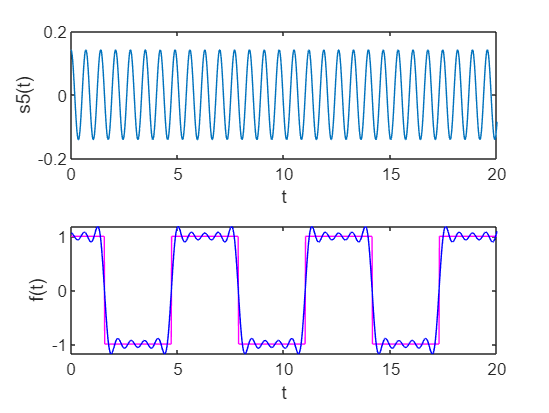

figure
subplot(2,1,1), plot(t, s5), xlabel('t'), ylabel('s5(t)');
subplot(2,1,2), plot(t,x2,'-m',t,s1+s2+s3+s4+s5,'-b'),xlabel('t'),ylabel('f(t)');

结论：如答图所示。

(d)

题目要求：分别计算系统对各个谐波分量的响应，并将输出信号求和，与相加后的响应作比较。

ys1 = lsim(B, A, s1, t)'

ys1 =     0.0000    0.0252    0.0500    0.0742    0.0979    0.1211    0.1438    0.1659    0.1876    0.2087    0.2294    0.2495    0.2691    0.2883    0.3069    0.3250    0.3425    0.3596    0.3762    0.3923    0.4078    0.4229    0.4374    0.4515    0.4650    0.4781    0.4906    0.5027    0.5142    0.5252    0.5358    0.5458    0.5554    0.5645    0.5731    0.5812    0.5888    0.5959    0.6025    0.6087    0.6144    0.6196    0.6243    0.6286    0.6324    0.6357    0.6386    0.6410    0.6429    0.6444


ys2 = lsim(B, A, s2, t)'

ys2 =    -0.0000   -0.0084   -0.0166   -0.0246   -0.0323   -0.0398   -0.0470   -0.0538   -0.0603   -0.0664   -0.0722   -0.0776   -0.0825   -0.0870   -0.0911   -0.0947   -0.0978   -0.1005   -0.1027   -0.1044   -0.1056   -0.1063   -0.1065   -0.1062   -0.1055   -0.1042   -0.1025   -0.1003   -0.0976   -0.0945   -0.0909   -0.0869   -0.0826   -0.0778   -0.0727   -0.0672   -0.0614   -0.0553   -0.0489   -0.0422   -0.0353   -0.0283   -0.0210   -0.0136   -0.0061    0.0016    0.0092    0.0170    0.0247    0.0324


ys3 = lsim(B, A, s3, t)'

ys3 =     0.0000    0.0050    0.0099    0.0146    0.0191    0.0232    0.0270    0.0305    0.0336    0.0363    0.0385    0.0402    0.0415    0.0422    0.0425    0.0422    0.0415    0.0403    0.0386    0.0364    0.0338    0.0308    0.0274    0.0237    0.0197    0.0154    0.0109    0.0062    0.0014   -0.0034   -0.0083   -0.0132   -0.0179   -0.0226   -0.0271   -0.0313   -0.0353   -0.0390   -0.0424   -0.0454   -0.0479   -0.0501   -0.0517   -0.0529   -0.0536   -0.0539   -0.0536   -0.0528   -0.0516   -0.0498


ys4 = lsim(B, A, s4, t)'

ys4 =     0.0000   -0.0036   -0.0070   -0.0103   -0.0132   -0.0159   -0.0181   -0.0200   -0.0214   -0.0223   -0.0227   -0.0226   -0.0220   -0.0209   -0.0194   -0.0174   -0.0150   -0.0123   -0.0093   -0.0060   -0.0026    0.0009    0.0045    0.0080    0.0114    0.0146    0.0176    0.0203    0.0226    0.0245    0.0260    0.0270    0.0275    0.0275    0.0270    0.0261    0.0246    0.0227    0.0204    0.0177    0.0147    0.0115    0.0081    0.0045    0.0009   -0.0027   -0.0063   -0.0096   -0.0128   -0.0157


ys5 = lsim(B, A, s5, t)'

ys5 =     0.0000    0.0028    0.0054    0.0078    0.0099    0.0117    0.0129    0.0138    0.0141    0.0139    0.0133    0.0121    0.0105    0.0086    0.0063    0.0037    0.0010   -0.0017   -0.0045   -0.0071   -0.0096   -0.0118   -0.0136   -0.0151   -0.0160   -0.0166   -0.0165   -0.0160   -0.0151   -0.0136   -0.0118   -0.0096   -0.0071   -0.0044   -0.0016    0.0012    0.0040    0.0066    0.0089    0.0110    0.0126    0.0138    0.0146    0.0149    0.0146    0.0139    0.0126    0.0110    0.0090    0.0066


% 将谐波分量加和
ssum = s1+s2+s3+s4+s5;
% 求出和信号的响应
yss = lsim(B, A, ssum, t)'

yss =    -0.0000    0.0211    0.0416    0.0617    0.0813    0.1003    0.1186    0.1364    0.1536    0.1702    0.1862    0.2017    0.2166    0.2311    0.2452    0.2589    0.2722    0.2854    0.2983    0.3111    0.3239    0.3365    0.3492    0.3619    0.3746    0.3873    0.4001    0.4128    0.4256    0.4382    0.4508    0.4632    0.4753    0.4872    0.4988    0.5099    0.5206    0.5309    0.5406    0.5498    0.5585    0.5666    0.5742    0.5814    0.5881    0.5945    0.6006    0.6065    0.6122    0.6179


% 将信号的响应加和
yssum = ys1+ys2+ys3+ys4+ys5

yssum =     0.0000    0.0211    0.0416    0.0617    0.0813    0.1003    0.1186    0.1364    0.1536    0.1702    0.1862    0.2017    0.2166    0.2311    0.2452    0.2589    0.2722    0.2854    0.2983    0.3111    0.3239    0.3365    0.3492    0.3619    0.3746    0.3873    0.4001    0.4128    0.4256    0.4382    0.4508    0.4632    0.4753    0.4872    0.4988    0.5099    0.5206    0.5309    0.5406    0.5498    0.5585    0.5666    0.5742    0.5814    0.5881    0.5945    0.6006    0.6065    0.6122    0.6179


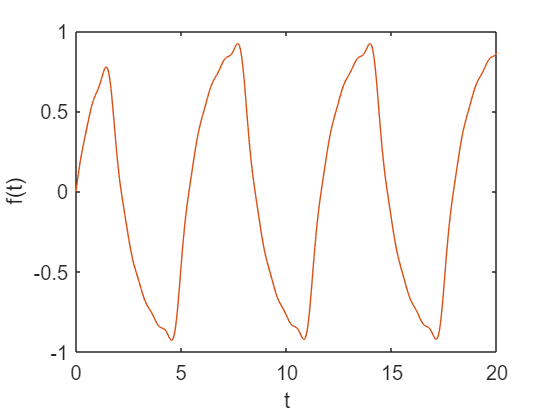

figure
plot(t,yss,t,yssum),xlabel('t'),ylabel('f(t)');

结论：如答图，yss与yssum信号是相同的，因此经过系统响应和求和的顺序不影响输出。

(e)

题目要求：将系统对前5次谐波之和的响应与系统对原方波的的响应作比较，解释其相似性。

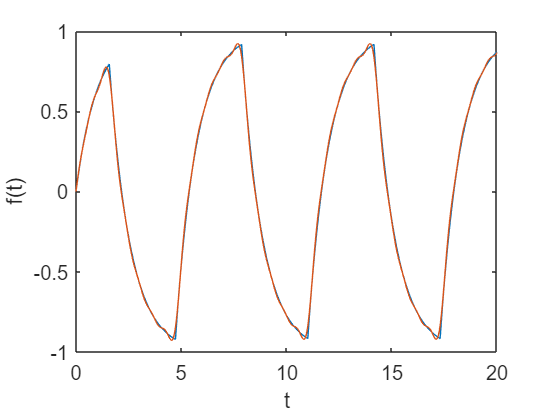

% 将两个响应绘制在同一张图上
figure
plot(t,y2,t,yss),xlabel('t'),ylabel('f(t)');

分析：如图，两个响应十分相似。原因在于，在谐波分量的数目增多时，谐波的和式趋近于原输入信号，因此能量也趋近与原信号的总能量，则对应的对同一个系统的响应逼近于原输入信号的响应。

(f)

题目要求：用H(s)和x2的CTFS构成信号验证各个谐波分量的响应是正确的，绘制用解析方法和仿真方法得到的信号。

分析：用解析方法得到响应，

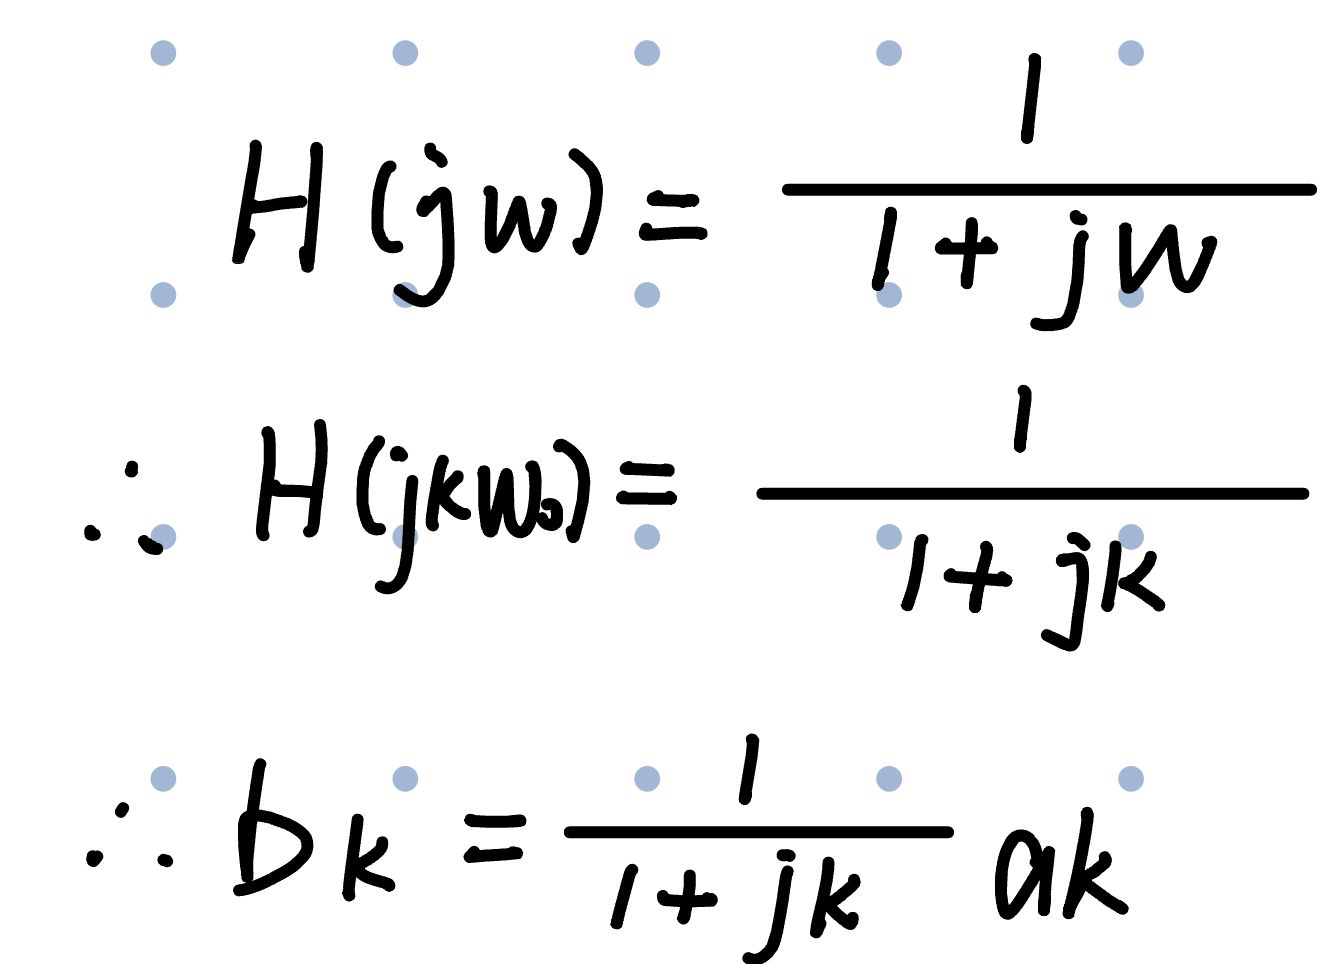

hys1 = lsim(1,[1 1],s1,t)'

hys1 =     0.0000    0.0252    0.0500    0.0742    0.0979    0.1211    0.1438    0.1659    0.1876    0.2087    0.2294    0.2495    0.2691    0.2883    0.3069    0.3250    0.3425    0.3596    0.3762    0.3923    0.4078    0.4229    0.4374    0.4515    0.4650    0.4781    0.4906    0.5027    0.5142    0.5252    0.5358    0.5458    0.5554    0.5645    0.5731    0.5812    0.5888    0.5959    0.6025    0.6087    0.6144    0.6196    0.6243    0.6286    0.6324    0.6357    0.6386    0.6410    0.6429    0.6444


hys2 = lsim(1,[1 2],s2,t)'

hys2 =     0.0000   -0.0083   -0.0163   -0.0239   -0.0311   -0.0379   -0.0443   -0.0502   -0.0558   -0.0608   -0.0654   -0.0696   -0.0733   -0.0765   -0.0792   -0.0815   -0.0833   -0.0845   -0.0854   -0.0857   -0.0856   -0.0850   -0.0839   -0.0825   -0.0805   -0.0782   -0.0755   -0.0723   -0.0688   -0.0649   -0.0607   -0.0562   -0.0514   -0.0462   -0.0409   -0.0353   -0.0295   -0.0234   -0.0173   -0.0110   -0.0046    0.0019    0.0085    0.0151    0.0217    0.0283    0.0348    0.0412    0.0476    0.0538


hys3 = lsim(1,[1 3],s3,t)'

hys3 =     0.0000    0.0049    0.0095    0.0138    0.0176    0.0210    0.0240    0.0265    0.0286    0.0302    0.0313    0.0319    0.0321    0.0318    0.0310    0.0298    0.0281    0.0261    0.0237    0.0209    0.0179    0.0145    0.0110    0.0072    0.0033   -0.0007   -0.0048   -0.0089   -0.0129   -0.0169   -0.0208   -0.0245   -0.0280   -0.0313   -0.0343   -0.0370   -0.0394   -0.0414   -0.0430   -0.0442   -0.0451   -0.0454   -0.0454   -0.0450   -0.0441   -0.0427   -0.0410   -0.0389   -0.0364   -0.0336


hys4 = lsim(1,[1 4],s4,t)'

hys4 =     0.0000   -0.0035   -0.0066   -0.0094   -0.0117   -0.0137   -0.0151   -0.0161   -0.0166   -0.0166   -0.0161   -0.0152   -0.0139   -0.0122   -0.0102   -0.0078   -0.0053   -0.0025    0.0004    0.0033    0.0063    0.0092    0.0119    0.0145    0.0168    0.0189    0.0206    0.0219    0.0229    0.0234    0.0235    0.0232    0.0224    0.0213    0.0197    0.0177    0.0155    0.0129    0.0101    0.0071    0.0040    0.0008   -0.0024   -0.0055   -0.0085   -0.0113   -0.0139   -0.0162   -0.0182   -0.0199


hys5 = lsim(1,[1 5],s5,t)'

hys5 =    -0.0000    0.0027    0.0050    0.0069    0.0084    0.0095    0.0101    0.0101    0.0097    0.0089    0.0077    0.0061    0.0042    0.0021   -0.0001   -0.0024   -0.0047   -0.0069   -0.0089   -0.0107   -0.0122   -0.0133   -0.0140   -0.0143   -0.0142   -0.0136   -0.0127   -0.0113   -0.0096   -0.0075   -0.0053   -0.0029   -0.0004    0.0021    0.0045    0.0067    0.0088    0.0105    0.0119    0.0129    0.0134    0.0136    0.0133    0.0125    0.0114    0.0098    0.0080    0.0059    0.0036    0.0012


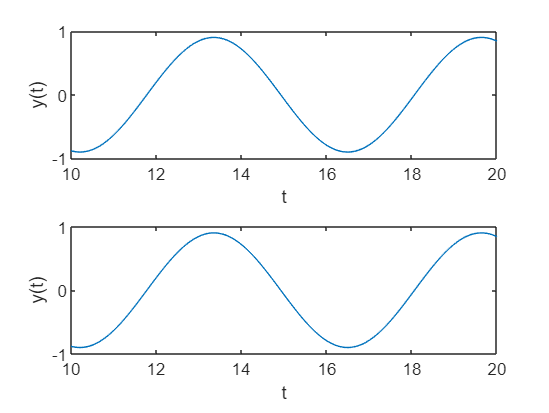

figure
subplot(2,1,1), plot(t, ys1), xlabel('t'), ylabel('y(t)'),axis([10 20 -1 1]);
subplot(2,1,2), plot(t, hys1), xlabel('t'), ylabel('y(t)'),axis([10 20 -1 1]);

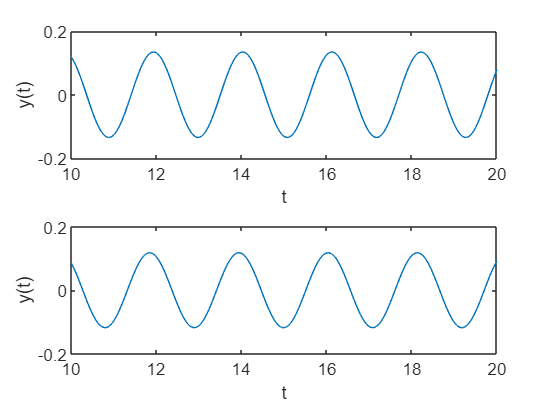

figure
subplot(2,1,1), plot(t, ys2), xlabel('t'), ylabel('y(t)'),axis([10 20 -0.2 0.2]);
subplot(2,1,2), plot(t, hys2), xlabel('t'), ylabel('y(t)'),axis([10 20 -0.2 0.2]);

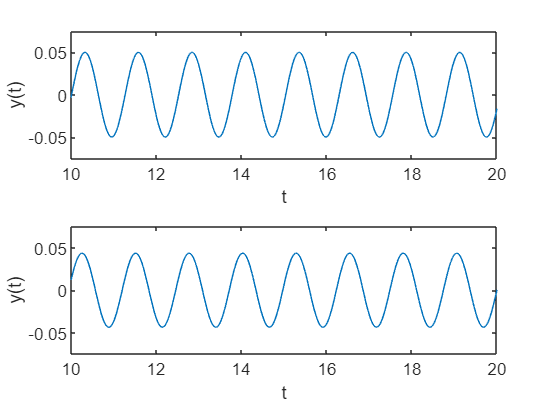

figure
subplot(2,1,1), plot(t, ys3), xlabel('t'), ylabel('y(t)'),axis([10 20 -0.075 0.075]);
subplot(2,1,2), plot(t, hys3), xlabel('t'), ylabel('y(t)'),axis([10 20 -0.075 0.075]);

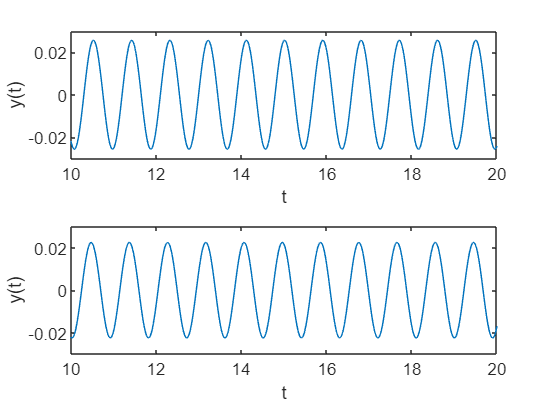

figure
subplot(2,1,1), plot(t, ys4), xlabel('t'), ylabel('y(t)'),axis([10 20 -0.03 0.03]);
subplot(2,1,2), plot(t, hys4), xlabel('t'), ylabel('y(t)'),axis([10 20 -0.03 0.03]);

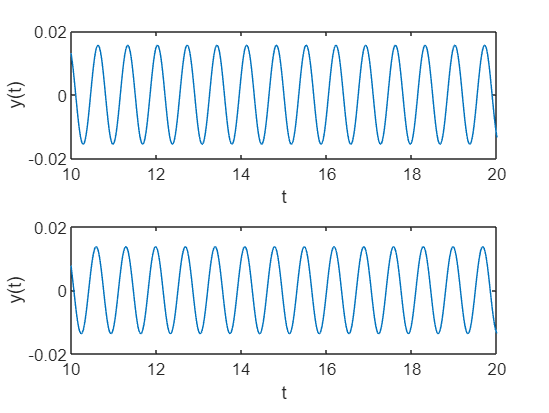

figure
subplot(2,1,1), plot(t, ys5), xlabel('t'), ylabel('y(t)'),axis([10 20 -0.02 0.02]);
subplot(2,1,2), plot(t, hys5), xlabel('t'), ylabel('y(t)'),axis([10 20 -0.02 0.02]);

结论：如答图所示，两信号基本一致。